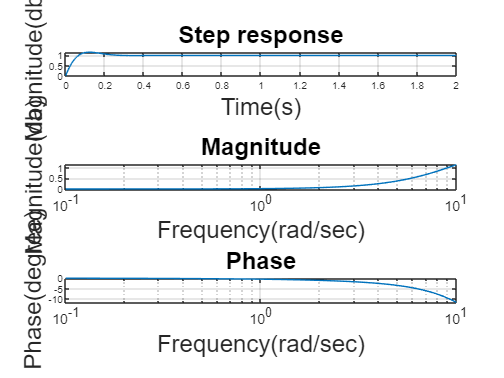

clc;clear all
omegan=20;
zeta=0.707;
a =25;
b =3.6;
kd = (2*zeta*omegan - b)/a;
kp = omegan^2/a;
num =[a*kd a*kp];
den = [1 2*zeta*omegan omegan^2];
sys=tf(num,den);
ts=4/(zeta*omegan);
tp=pi/(omegan*sqrt(1-zeta^2));
pos=exp(-zeta*pi/sqrt(1-zeta^2))*100;
t=0:0.01:2;
[yout,t]=step(sys,t);
max_y = max(yout);
subplot(3,1,1);
plot(t,yout)
title('Step response',FontSize=20)
xlabel('Time(s)',FontSize=20);
ylabel('Magnitude(db)',FontSize=20);
grid on
[Gm,Pm,Wcp,Wcg]=margin(sys);
w=logspace(-1,1,100);
[mag,phase]=bode(num,den,w);
subplot(3,1,2);
semilogx(w,20*log10(mag));
title('Magnitude',FontSize=20);
xlabel('Frequency(rad/sec)',FontSize=20);
ylabel('Magnitude(db)',FontSize=20);
grid;
subplot(3,1,3);
semilogx(w,phase);grid;
title('Phase',FontSize=20)
xlabel('Frequency(rad/sec)',FontSize=20);
ylabel('Phase(degree)',FontSize=20);